### Drogue Size vs. Mass Trade (keeping SYS.07 at 0.10 m)

Question this file answers: how big can the drogue mouth get before it breaks one of our hard limits, and does that size cover the 0.10 m radial offset? The mouth is enlarged with a thin flared skirt on the front of the drogue, which adds far less mass than scaling the whole part.

Hard limits checked: (1) docking hardware on the ABV must stay under 2.35 kg, the most added mass the PID controller handled in the Lovelace thesis; (2) it must not tip the ABV (ARL tank-side test); (3) it must print in one piece on the H2D/H2C (300 mm bed); (4) it must not be wider than the ABV (343 mm); (5) the skirt wall must be steep enough for the probe to slide.

The lower bound comes from how accurately GNC delivers the ABV: the drogue must at least catch the ABV’s own position error. That error is estimated from GNC simulation runs (only 4 so far; reminder to run 15-20 more).

clear; clc; close all;
in2m = 0.0254;

% ---- Current design (Fusion CAD) ----
r_nose   = 0.0143;          % m, probe nose radius
R_base   = 0.0554;          % m, original drogue opening, where the skirt starts
R_now    = 0.111;           % m, current mouth radius (60° skirt)
skirt_now = 60;             % deg
V_body   = 498.1e-6;        % m^3, drogue without skirt
V_skirt_cad = (642.4 - 498.1) * 1e-6;   % m^3, skirt actually in the CAD (incl. its rim)
V_bracket   = (145.6 + 60.0) * 1e-6;    % m^3, bracket plate + clips
L_body   = 0.0838;          % m, drogue body depth
t_plate  = 0.00635;         % m, bracket plate thickness

% ---- Materials and allowances ----
rho      = 1300;            % kg/m^3, OVERTURE PETG datasheet (TDS v5.2)
growth   = 1.15;            % x for bolts and brass inserts not in CAD
t_wall   = 0.003;           % m, skirt wall thickness

% ---- Hard limits ----
m_limit  = 2.35;                              % kg, PID controller limit (thesis)
mr_limit = 1.695 * (26 - 13.5) * in2m;        % kg*m, tank-side tipping limit (ARL test, about the edge)
bed      = 0.300;                             % m, H2D/H2C print bed (smaller side)
abv_w    = 13.5 * in2m;                       % m
max_slide = 61.8;                             % deg, flattest skirt that still slides, PETG on PETG (capture_geometry)

% ---- Requirement and margins (same as capture_geometry) ----
SYS07     = 0.100;   % m
pos_error = 0.005;   % m
margin    = 0.010;   % m
need      = SYS07 + pos_error + margin;      % m, catch range needed (mouth radius minus nose radius)

% ---- Lower bound from GNC accuracy ----
sim_lateral_mm = [4.2 -2.0 -5.2 4.1];   % mm, sideways error at contact in GNC sim runs (Meeting 6)
hw_factor = 2.0;     % real hardware assumed 2x more scattered than the sim (confirm with table runs)
optitrack = 0.001;   % m, OptiTrack position error (estimate; read from Motive calibration)

% ---- Skirt design to evaluate ----
skirt_deg = 50;      % deg, recommended (sliding margin ~12 deg); current is 60

### Calculations

The thin-shell skirt estimate is scaled so it matches the skirt mass in the current CAD (the CAD skirt also has a rim). Catch range = mouth radius minus probe nose radius.

shell = @(R, ang) t_wall * pi * (R_base + R) .* ((R - R_base) ./ sind(ang));   % m^3, thin cone shell
rim_factor = V_skirt_cad / shell(R_now, skirt_now);                              % CAD / thin shell

sigma = sqrt(mean((sim_lateral_mm/1000).^2));
floor_need = 3*sigma*hw_factor + optitrack + pos_error;     % m, smallest catch range that is still safe

R   = linspace(R_base, 0.17, 400);                 % m, candidate mouth radii
cap = R - r_nose;                                  % m, catch range
L_s = (R - R_base) / tand(skirt_deg);              % m, skirt length
V_s = shell(R, skirt_deg) * rim_factor;            % m^3
m_hw = (V_body + V_bracket + V_s) * rho * growth;  % kg

% Tipping: each part's mass times its distance past the ABV front edge
mr = growth * rho * ( V_body*(t_plate + 0.0527) + 145.6e-6*0.0032 + 60.0e-6*(-0.0233) ...
                    + V_s .* (t_plate + L_body + L_s/2) );

ok_mass  = m_hw <= m_limit;
ok_tip   = mr <= mr_limit;
ok_bed   = 2*(R + t_wall) <= bed;
ok_width = 2*(R + t_wall) <= abv_w;
ok_slide = skirt_deg <= max_slide - 5;
ok = ok_mass & ok_tip & ok_bed & ok_width & ok_slide;
best = find(ok, 1, 'last');

### Results

pick = [R_now, need + r_nose, R(best)];
Option = ["Current drogue (60° skirt)"; sprintf("Meets SYS.07 (%d° skirt)", skirt_deg); "Largest that fits all limits"];
mh = zeros(3,1); L = zeros(3,1); m_r = zeros(3,1);
for k = 1:3
    if k == 1
        mh(k) = (V_body + V_bracket + V_skirt_cad) * rho * growth;  L(k) = (R_now - R_base)/tand(skirt_now);
        m_r(k) = growth*rho*( V_body*(t_plate+0.0527) + 145.6e-6*0.0032 + 60e-6*(-0.0233) + V_skirt_cad*(t_plate+L_body+L(k)/2) );
    else
        [~, i] = min(abs(R - pick(k)));  mh(k) = m_hw(i);  L(k) = L_s(i);  m_r(k) = mr(i);
    end
end
Options = table(Option, pick'*1e3*2, (pick' - r_nose)*1e3, L*1e3, mh, m_r, ...
    'VariableNames', {'Design', 'Mouth diameter (mm)', 'Catch range (mm)', 'Skirt length (mm)', ...
    'Hardware mass (kg)', 'Tipping load (kg·m)'})

Options = 3×6 table
                Design                Mouth diameter (mm)    Catch range (mm)    Skirt length (mm)    Hardware mass (kg)    Tipping load (kg·m)
    ______________________________    ___________________    ________________    _________________    __________________    ___________________

    "Current drogue (60° skirt)"               222                  96.7              32.101                1.2678               0.065489      
    "Meets SYS.07 (50° skirt)"               258.6                   115              61.938                1.4113               0.086088      
    "Largest that fits all limits"          293.47                132.44              76.639                1.5387                 0.1051      



Limits = table(["PID mass limit"; "Tipping limit"; "Print bed"; "ABV width"; "GNC floor (min catch range)"], ...
    [m_limit; mr_limit; bed*1e3; abv_w*1e3; floor_need*1e3], ["kg"; "kg·m"; "mm"; "mm"; "mm"], ...
    'VariableNames', {'Limit', 'Value', 'Units'})

Limits = 5×3 table
                Limit                 Value     Units 
    _____________________________    _______    ______

    "PID mass limit"                    2.35    "kg"  
    "Tipping limit"                  0.53816    "kg·m"
    "Print bed"                          300    "mm"  
    "ABV width"                        342.9    "mm"  
    "GNC floor (min catch range)"     30.278    "mm"  



fprintf('Current drogue catches %.0f mm; SYS.07 with margins needs %.0f mm.\n', (R_now - r_nose)*1e3, need*1e3);

Current drogue catches 97 mm; SYS.07 with margins needs 115 mm.


if (need + r_nose) <= R(best)
    fprintf('RESULT: KEEP SYS.07 = 0.10 m. A %d° skirt to a %.0f mm mouth meets every limit\n', skirt_deg, 2*(need + r_nose)*1e3);
    fprintf('(hardware %.2f of %.2f kg). Largest mouth that fits all limits: %.0f mm.\n', mh(2), m_limit, 2*R(best)*1e3);
else
    fprintf('RESULT: RESCOPE SYS.07 to %.0f mm, the largest catch range all limits allow.\n', floor((R(best) - r_nose - pos_error - margin)*200)/200*1e3);
end

RESULT: KEEP SYS.07 = 0.10 m. A 50° skirt to a 259 mm mouth meets every limit


(hardware 1.41 of 2.35 kg). Largest mouth that fits all limits: 293 mm.


comb = need + (0.1715 + 0.1228)*sind(4);
fprintf('Combined test: turning about the drogue mouth (team sketch) keeps the need at %.0f mm.\n', need*1e3);

Combined test: turning about the drogue mouth (team sketch) keeps the need at 115 mm.


fprintf('Turning about the ABV center would need %.0f mm (a %.0f mm mouth), past every limit.\n', comb*1e3, 2*(comb + r_nose)*1e3);

Turning about the ABV center would need 136 mm (a 300 mm mouth), past every limit.


fprintf('GNC floor: %.0f mm (from %d sim runs; run 15-20 more to firm this up).\n', floor_need*1e3, numel(sim_lateral_mm));

GNC floor: 30 mm (from 4 sim runs; run 15-20 more to firm this up).


### Skirt to draw in Fusion

Dimensions for the recommended skirt, measured from the drogue centerline. The skirt keeps the existing drogue body and starts where the original opening is (55.4 mm radius). Only the skirt changes: it gets steeper (60° to 50° from the centerline) and longer, so the mouth grows from 222 mm to about 259 mm across.

R_end = need + r_nose;                                    % m, mouth radius needed
Ls    = (R_end - R_base) / tand(skirt_deg);                % m, skirt length along the centerline
V_new = shell(R_end, skirt_deg) * rim_factor;
Item  = ["Wall angle from the centerline"; "Start radius (existing opening)"; "Mouth radius"; ...
         "Mouth diameter"; "Skirt length along the centerline"; "Wall thickness"; ...
         "Skirt mass (PETG, incl. rim)"; "Total drogue + bracket mass"];
Value = [skirt_deg; R_base*1e3; R_end*1e3; 2*R_end*1e3; Ls*1e3; t_wall*1e3; ...
         V_new*rho*1e3; (V_body + V_bracket + V_new)*rho*growth];
Units = ["deg"; "mm"; "mm"; "mm"; "mm"; "mm"; "g"; "kg"];
SkirtDrawing = table(Item, Value, Units, 'VariableNames', {'Dimension', 'Recommended', 'Units'})

SkirtDrawing = 8×3 table
                 Dimension                 Recommended    Units
    ___________________________________    ___________    _____

    "Wall angle from the centerline"             50       "deg"
    "Start radius (existing opening)"          55.4       "mm" 
    "Mouth radius"                            129.3       "mm" 
    "Mouth diameter"                          258.6       "mm" 
    "Skirt length along the centerline"      62.009       "mm" 
    "Wall thickness"                              3       "mm" 
    "Skirt mass (PETG, incl. rim)"           312.87       "g"  
    "Total drogue + bracket mass"            1.4118       "kg" 


fprintf('Why %d° and not the current %d°: at %d° the probe sticks if friction is above %.2f, and printed\n', ...
    skirt_deg, skirt_now, skirt_now, tand(90 - skirt_now - 4));

Why 50° and not the current 60°: at 60° the probe sticks if friction is above 0.49, and printed


fprintf('PETG on PETG is about 0.3-0.6. At %d° it keeps sliding up to a friction of %.2f.\n', skirt_deg, tand(90 - skirt_deg - 4));

PETG on PETG is about 0.3-0.6. At 50° it keeps sliding up to a friction of 0.73.


### Plots

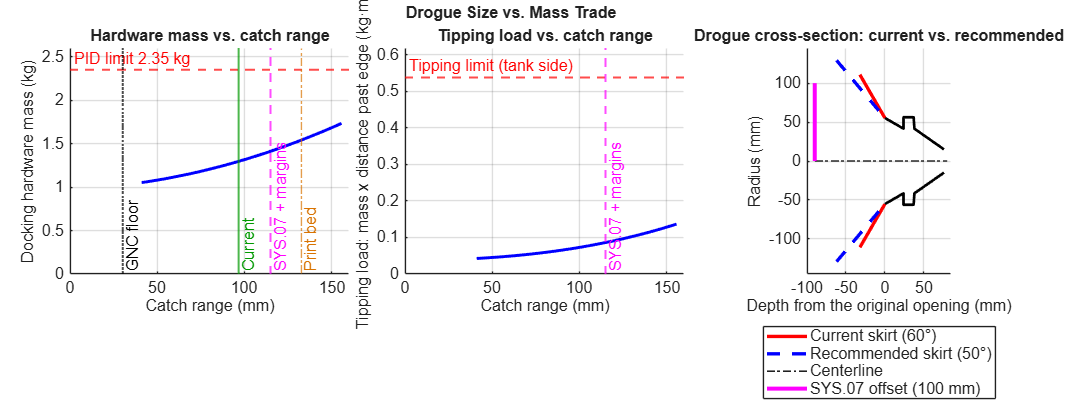

fig = figure('Name', 'Drogue Trade', 'Position', [60 60 1350 520]);
theme(fig, 'light');
tl = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; hold on;
plot(cap*1e3, m_hw, 'b-', 'LineWidth', 2.2, 'DisplayName', sprintf('%d° skirt', skirt_deg));
yline(m_limit, 'r--', 'PID limit 2.35 kg', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelHorizontalAlignment', 'left');
xline(floor_need*1e3, 'k:', 'GNC floor', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom');
xline((R_now - r_nose)*1e3, 'Color', [0 0.6 0], 'LineWidth', 1.5, 'Label', 'Current', 'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom');
xline(need*1e3, 'm--', 'SYS.07 + margins', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom');
nb = find(~ok_bed, 1);
if ~isempty(nb), xline(cap(nb)*1e3, 'Color', [0.85 0.45 0], 'LineStyle', '-.', 'Label', 'Print bed', 'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom'); end
xlabel('Catch range (mm)'); ylabel('Docking hardware mass (kg)');
title('Hardware mass vs. catch range'); xlim([0 160]); ylim([0 2.6]); grid on;

nexttile; hold on;
plot(cap*1e3, mr, 'b-', 'LineWidth', 2.2);
yline(mr_limit, 'r--', 'Tipping limit (tank side)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left');
xline(need*1e3, 'm--', 'SYS.07 + margins', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');
xlabel('Catch range (mm)'); ylabel('Tipping load: mass x distance past edge (kg·m)');
title('Tipping load vs. catch range'); xlim([0 160]); ylim([0 mr_limit*1.15]); grid on;

nexttile; hold on;
% Half cross-section of the drogue inner surface (mouth at depth 0; probe comes from the left)
body = [0 55.4; 24 41.5; 24 56.2; 37 56.2; 38 41.5; 76 14.9];           % mm [depth, radius], CAD
cur  = [-(R_now - R_base)/tand(skirt_now)*1e3, R_now*1e3; 0 R_base*1e3];
new  = [-Ls*1e3, R_end*1e3; 0 R_base*1e3];
for sgn = [1 -1]
    plot(body(:,1), sgn*body(:,2), 'k-', 'LineWidth', 2, 'HandleVisibility', 'off');
end
plot(cur(:,1), cur(:,2), 'r-', 'LineWidth', 2.5, 'DisplayName', sprintf('Current skirt (%d°)', skirt_now));
plot(cur(:,1), -cur(:,2), 'r-', 'LineWidth', 2.5, 'HandleVisibility', 'off');
plot(new(:,1), new(:,2), 'b--', 'LineWidth', 2.5, 'DisplayName', sprintf('Recommended skirt (%d°)', skirt_deg));
plot(new(:,1), -new(:,2), 'b--', 'LineWidth', 2.5, 'HandleVisibility', 'off');
plot([-90 80], [0 0], 'k-.', 'LineWidth', 1, 'DisplayName', 'Centerline');
plot([-90 -90], [0 SYS07*1e3], 'm-', 'LineWidth', 3, 'DisplayName', 'SYS.07 offset (100 mm)');
axis equal; xlim([-100 85]); ylim([-145 145]);
xlabel('Depth from the original opening (mm)'); ylabel('Radius (mm)');
title('Drogue cross-section: current vs. recommended'); legend('Location', 'southoutside'); grid on;

title(tl, 'Drogue Size vs. Mass Trade', 'FontWeight', 'bold');
fontsize(fig, 12, 'points');